# Beam steering with a LCOS-SLM

- Simulation of a blazed phase stepped grating with a number N of equidistant phase steps for two cases: without quantization & 2𝜋 phase modulation.

- Meaning of the used parameters: M = maximum phase depth, alpha = diffraction order, N = phase steps, lamda = wavelength, pixel_pitch = pixel pitch of the SLM.

- Exported parameters: diff_eff: diffraction efficiency, the use of 0th denotes zeroth diffraction order

First Case: Without Quantization (continuous phase grating)

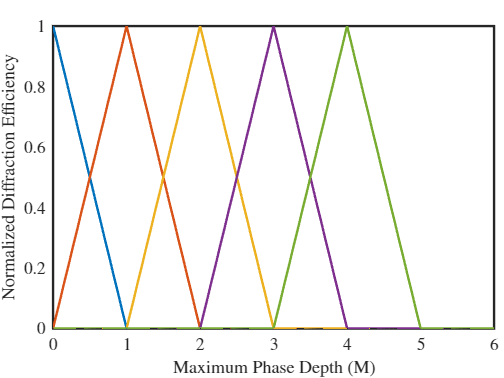

clear all; clc
iter = 0;
for M = 0:6
    iter = iter + 1;
    alpha_0th = 0;
    diff_eff_0th(iter) = sinc(M-alpha_0th)^2;    
    alpha_1th = 1;
    diff_eff_1th(iter) = sinc(M-alpha_1th)^2;
    alpha_2th = 2;
    diff_eff_2th(iter) = sinc(M-alpha_2th)^2;    
    alpha_3th = 3;
    diff_eff_3th(iter) = sinc(M-alpha_3th)^2; 
    alpha_4th = 4;
    diff_eff_4th(iter) = sinc(M-alpha_4th)^2;      
end
M=0:6;
figure; plot(M,diff_eff_0th,'LineWidth',2)
hold on
plot(M,diff_eff_1th,'LineWidth',2)
plot(M,diff_eff_2th,'LineWidth',2)
plot(M,diff_eff_3th,'LineWidth',2)
plot(M,diff_eff_4th,'LineWidth',2)
hold off
xlabel ('Maximum Phase Depth (M)','Interpreter','latex');ylabel ('Normalized Diffraction Efficiency','Interpreter','latex');
set(gca,'Linewidth',2);set(gca,'TickLabelInterpreter','latex');set(gca,'TickLength',[0, 0]);set(gca,'LooseInset',max(get(gca,'TightInset'), 0.02))
ax=gca;ax.FontSize=14;pos=get(gca,'pos');set(gca,'pos',[pos(1) pos(2) pos(3) pos(4)*.95]);

%print('without_quantization','-dsvg','-r600') % save high-quality figure

  Second Case: 2π phase modulation (M=1)

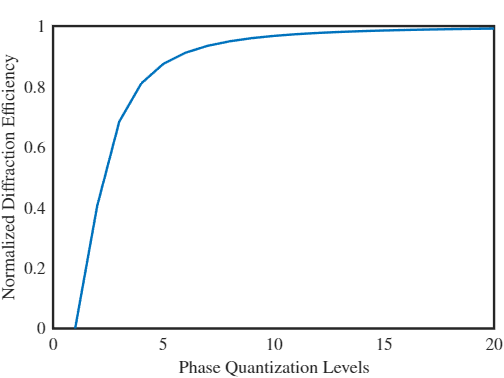

clear all; clc
iter = 0;
for N = 0:20
    iter = iter + 1;
    diff_eff(iter) = sinc(1/N)^2;
end
N=0:20;
figure; plot(N,diff_eff,'LineWidth',2)
xlabel ('Phase Quantization Levels (N)','Interpreter','latex');ylabel ('Normalized Diffraction Efficiency','Interpreter','latex');
set(gca,'Linewidth',2);set(gca,'TickLabelInterpreter','latex');set(gca,'TickLength',[0, 0]);set(gca,'LooseInset',max(get(gca,'TightInset'), 0.02))
ax=gca;ax.FontSize=14;pos=get(gca,'pos');set(gca,'pos',[pos(1) pos(2) pos(3) pos(4)*.95]);

%print('phaseModulation','-dsvg','-r600') % save high-quality figure

Bonus Case: Study of steering angle of a given blazed grating  

clear all; clc
alpha = ; lamda = ; pixel_pitch = 6.4e-6; N =;
steering_angle = asin (alpha*lamda/N*pixel_pitch)

Critical paper for understanding the code:

#### Moreno, I. *et al.* Diffraction efficiency of stepped gratings using high phase-modulation spatial light modulators. *Optics and Lasers in Engineering* **126**, 105910 (2020).  

**Christos Tselios, PhD student ece uop X ISI, project: LCOS X WSS (part I)**